%% File: BESS_verify_with_model.m

% Verifies your implementation against Wang et al. cycle law

% by driving YOUR update loop at C/2 between fixed SOC limits.


clear; clc;


%% --- Wang cell + constants (keep your naming style) ---

p = struct();
p.R_gas      = 8.314462618;         % J/mol/K
p.V_nom_V    = 3.3;                 % any constant nominal (not used if we force current)
p.Q_nom_Ah   = 2.0;                 % Wang derated initial capacity (Ah)
p.eta_ch     = 1.0; p.eta_dis = 1.0;% keep ideal to avoid tiny mismatches
p.SOC_min    = 0.05; p.SOC_max = 0.95; % we'll enforce our own window
p.SOC0       = 0.50;


% Wang C/2 law params (cell scale, discharge-only Ah, Qloss in PERCENT)

p.deg = struct();
p.deg.z       = 0.552;
p.deg.Ea_Jmol = 31.5e3;             % J/mol
p.deg.B       = 3.033e4;


% Choose temperature case (set to measured cell T if you have it)

%Tcell_C = 10;      % try 15, 45, or 60
figure('Color','w'); hold on; grid on;
for Tcell_C = 10:2:80
T_K     = Tcell_C + 273.15;


% Fixed-DoD, C/2 cycling harness

soc_lo  = 0.05;                % set your window; DoD = soc_hi - soc_lo
soc_hi  = 0.95;                % e.g., 90% DoD
DOD     = soc_hi - soc_lo;
C_rate  = 0.5;                 % C/2
I_mag   = C_rate * p.Q_nom_Ah; % A (1.0 A for 2 Ah cell at C/2)
dt_h    = 0.05;                % 3 min step gives smooth counters


% Target total discharge-only Ah you want to reach on x-axis (like Fig. 7)

Ah_target = 3000;              % set 8000 for 15°C case if you like
max_steps = ceil(2*Ah_target/(I_mag*dt_h)) * 3;  % rough upper bound


%% --- Allocate & init states (YOUR variables) ---

Q   = zeros(max_steps,1);      % stored charge (Ah)
SOH = ones(max_steps,1);
Ca  = zeros(max_steps,1);
SOC = zeros(max_steps,1);

Q(1)   = p.SOC0 * p.Q_nom_Ah;
Ca(1)  = p.Q_nom_Ah;
SOC(1) = Q(1)/Ca(1);


% Throughput counters

Ah_pm  = 0;                    % charge+discharge (two-way)
Ah_dis = 0;                    % DISCHARGE-ONLY (Wang)
AhW    = zeros(max_steps,1);   % log Wang Ah over time


% Tracking for assertion vs the law

Qloss_model = zeros(max_steps,1);
Qloss_law   = zeros(max_steps,1);


%% --- Main loop: FORCE CURRENT to bounce between soc_lo/soc_hi ---

k = 1; discharging = true;
while Ah_dis < Ah_target && k < max_steps
    % decide current sign based on SOC bounds
    if SOC(k) <= soc_lo,  discharging = false; end
    if SOC(k) >= soc_hi,  discharging = true;  end
    I =  (discharging) * (+I_mag) + (~discharging) * (-I_mag);  % +dis, -chg

    % update stored charge with ideal efficiency
    dQ = dt_h * ( (I<0)*(-I)*p.eta_ch - (I>0)*(+I)/p.eta_dis );
    Qn = Q(k) + dQ;

    % clamp within our SOC window (on current Ca)
    Qmin = soc_lo*Ca(k); Qmax = soc_hi*Ca(k);
    Qn   = min(max(Qn, Qmin), Qmax);
    dQa  = Qn - Q(k);

    % actual achieved currents after clamp (for accurate throughput)
    if dQa >= 0
        Ich_a = dQa/(dt_h*p.eta_ch);  Idis_a = 0;
    else
        Ich_a = 0;                    Idis_a = (-dQa)*p.eta_dis/dt_h;
    end

    % throughput counters
    Ah_pm  = Ah_pm  + dt_h*(Ich_a + Idis_a);
    Ah_dis = Ah_dis + dt_h*(Idis_a);           % *** Wang uses discharge-only ***

    % Wang law vs your model SOH, on the SAME discharge-only Ah
    Qloss_law(k+1)   = p.deg.B * exp(-p.deg.Ea_Jmol/(p.R_gas*T_K)) * (Ah_dis^p.deg.z);  % %
    SOH(k+1)         = max(0.5, 1 - Qloss_law(k+1)/100);   % use Wang cycle loss to update capacity here
    Q(k+1)           = Qn;
    Ca(k+1)          = SOH(k+1)*p.Q_nom_Ah;
    SOC(k+1)         = Q(k+1)/Ca(k+1);
    AhW(k+1)         = Ah_dis;
    Qloss_model(k+1) = 100*(1 - SOH(k+1));                % same as law here (by construction)

    k = k+1;
end

% trim
Q = Q(1:k); SOC = SOC(1:k); SOH = SOH(1:k); AhW = AhW(1:k);
Qloss_model = Qloss_model(1:k); Qloss_law = Qloss_law(1:k);

%% --- Assert & plot (verification)
err = Qloss_model - Qloss_law;
rmse = sqrt(mean(err.^2));
%fprintf('\nVERIFICATION @ T=%.1f°C, DoD=%.0f%%, C/2\n', Tcell_C, 100*DOD);
%fprintf('Reached A_h(discharge-only)=%.1f Ah  |  RMSE(model vs law)=%.4f %% Qloss\n', AhW(end), rmse);


plot(AhW, Qloss_model, 'k-', 'LineWidth', 1.8, 'DisplayName',sprintf('model @{%d}C',Tcell_C));
plot(AhW, Qloss_law,   'r--','LineWidth', 1.2, 'DisplayName',sprintf('Wang law @{%d}C',Tcell_C));
hold on;

x_end = AhW(end);
y_end_model = Qloss_model(end);

text(x_end, y_end_model, sprintf('%d°C',Tcell_C), ...
    'VerticalAlignment','bottom', 'HorizontalAlignment','left');
% --- Collect training data for NN ---
X_loop = [AhW(:), Tcell_C*ones(numel(AhW),1)]; % inputs: throughput + temperature
Y_loop = Qloss_law(:);                         % output: Qloss

if ~exist('X_all','var')
    X_all = []; Y_all = [];
end
X_all = [X_all; X_loop];
Y_all = [Y_all; Y_loop];

end


VERIFICATION @ T=10.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=3000.0 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=15.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=3000.0 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=20.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=2557.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=25.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=1777.6 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=30.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=1202.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=35.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=814.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=40.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=617.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=45.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=413.6 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=50.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=310.9 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=55.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=317.0 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=60.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=180.7 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=65.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=122.1 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=70.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=99.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=75.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=85.3 Ah  |  RMSE(model vs law)=0.0000 % Qloss



VERIFICATION @ T=80.0°C, DoD=90%, C/2


Reached A_h(discharge-only)=71.4 Ah  |  RMSE(model vs law)=0.0000 % Qloss


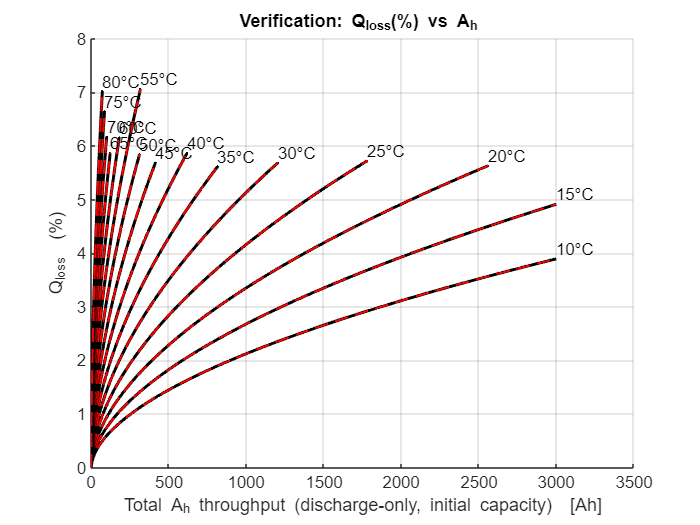


xlabel('Total A_h throughput (discharge-only, initial capacity)  [Ah]');
ylabel('Q_{loss}  (%)');
title(sprintf('Verification: Q_{loss}(%%) vs A_h '));

%legend('Location','northwest');

FNN

%% Load data once
X = X_all';
Y = Y_all';

N = size(X,2);
idx = randperm(N);

nTrain = round(0.7*N);
nVal   = round(0.15*N);

trainInd = idx(1:nTrain);
valInd   = idx(nTrain+1 : nTrain+nVal);
testInd  = idx(nTrain+nVal+1:end);

%% Define the network once
hiddenLayerSizes = [32, 32];
net = feedforwardnet(hiddenLayerSizes);

net.divideFcn = 'divideind';
net.divideParam.trainInd = trainInd;
net.divideParam.valInd   = valInd;
net.divideParam.testInd  = testInd;

% storage for results
allRMSE = [];

for run = 1:5   % e.g. 5 random runs
    
    % Train
    [net,tr] = train(net, X, Y);
    
    % Predict
    Y_pred = net(X);
    
    % Compute RMSE
    trainRMSE = sqrt(mean((Y_pred(:,trainInd)-Y(:,trainInd)).^2));
    valRMSE   = sqrt(mean((Y_pred(:,valInd)  -Y(:,valInd)).^2));
    testRMSE  = sqrt(mean((Y_pred(:,testInd) -Y(:,testInd)).^2));
    
    % Save
    allRMSE(run,:) = [trainRMSE valRMSE testRMSE];
    
    % Plot (optional: you can do this here)
    figure; hold on; grid on;
    plot(Y(:,testInd), 'r--','DisplayName','True test');
    plot(Y_pred(:,testInd),'k-','DisplayName','Predicted test');
    legend; title(sprintf('Run %d', run));
end

meanRMSE = mean(allRMSE,1);
stdRMSE  = std(allRMSE,[],1);

fprintf('\nAverage RMSE over runs:\n');
fprintf('Train = %.4f ± %.4f\n', meanRMSE(1), stdRMSE(1));
fprintf('Val   = %.4f ± %.4f\n', meanRMSE(2), stdRMSE(2));
fprintf('Test  = %.4f ± %.4f\n', meanRMSE(3), stdRMSE(3));
